# Change connectivity of lateral pathway

## 0.3_0.03

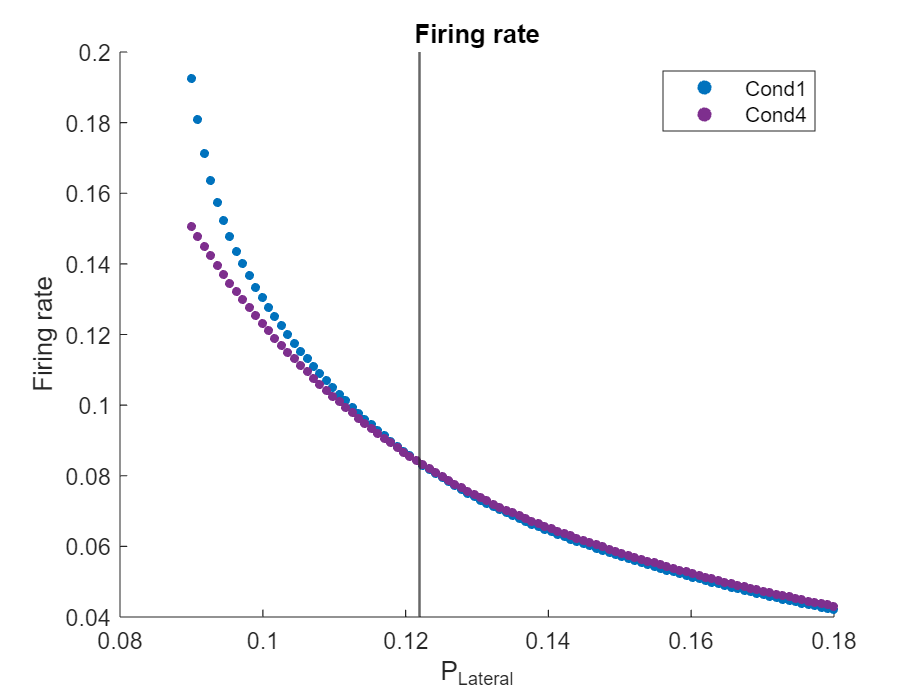

load lateral\finalR_cLateral_0.09_0.18_DeltaE_0.3_DeltaI_0.03_Iattn_0.02.mat
addpath('funcs');

lateral_start = 0.09;
lateral_end = 0.18; 

steps = 100;

sz = 15;
x = linspace(lateral_start,lateral_end,size(PETAsheet,1));
y1 = finalRsheet(:,5,1);
y4 = finalRsheet(:,5,4);

% find zero point
z = y1 - y4; 
[~, idxP] = min(z(z>0));
x0 = (x(idxP) + x(idxP+1))/2;

figure();
s1 = scatter(x,y1,sz,'filled','MarkerFaceColor','#0072BD');
hold on;
s4 = scatter(x,y4,sz,'filled','MarkerFaceColor','#7E2F8E');
xline(x0,'LineWidth',1);

title("Firing rate");
legend([s1 s4],["Cond1","Cond4"]);
xlabel("P_{Lateral}");
ylabel("Firing rate");

## Lateral Pathway

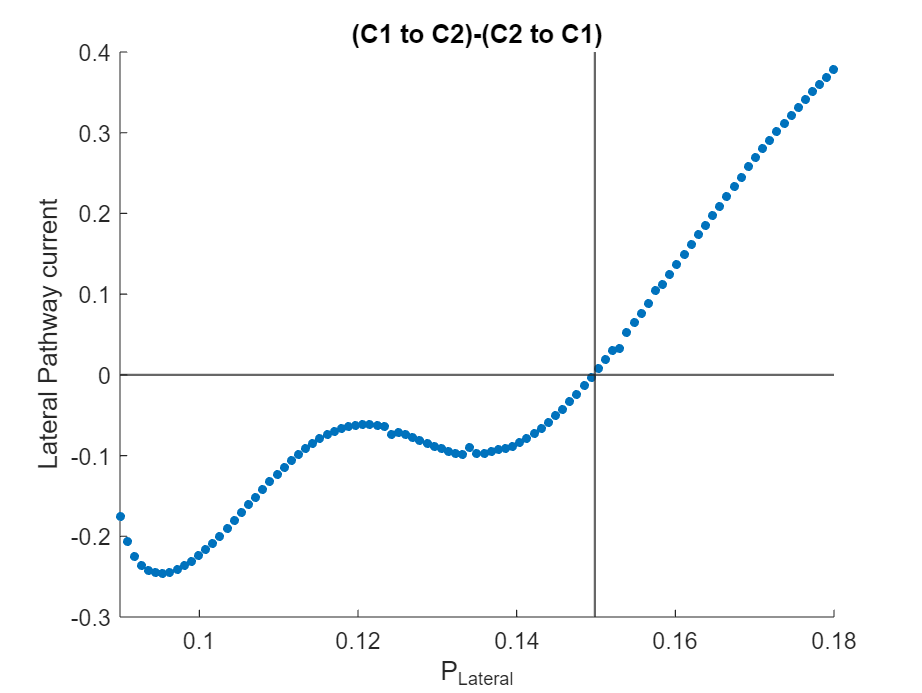

load lateral\finalR_cLateral_0.09_0.18_DeltaE_0.3_DeltaI_0.03_Iattn_0.02.mat
addpath('funcs');

lateral_start = 0.09;
lateral_end = 0.18; 

steps = 100;

sz = 15;
x = linspace(lateral_start,lateral_end,size(PETAsheet,1));
y1 = PETAsheet(:,10,1,4);
y2 = PETAsheet(:,2,9,4);

% find zero point
z = y2 - y1; 
[~, idxP] = min(z(z>0));
x0 = (x(idxP) + x(idxP+1))/2;

figure();
s1 = scatter(x,y1-y2,sz,'filled','MarkerFaceColor',"#0072BD");
hold on;
% s2 = scatter(x,y2,sz,'filled','MarkerFaceColor',"#D95319");
xline(x0,'LineWidth',1);
yline(0,'LineWidth',1);

xlim([0.09 0.18]);
title("(C1 to C2)-(C2 to C1)");
% legend([s1 s2],["C1 to C2","C2 to C1"],"Location","Southeast");
xlabel("P_{Lateral}");
ylabel("Lateral Pathway current");

## 0.3_0.026

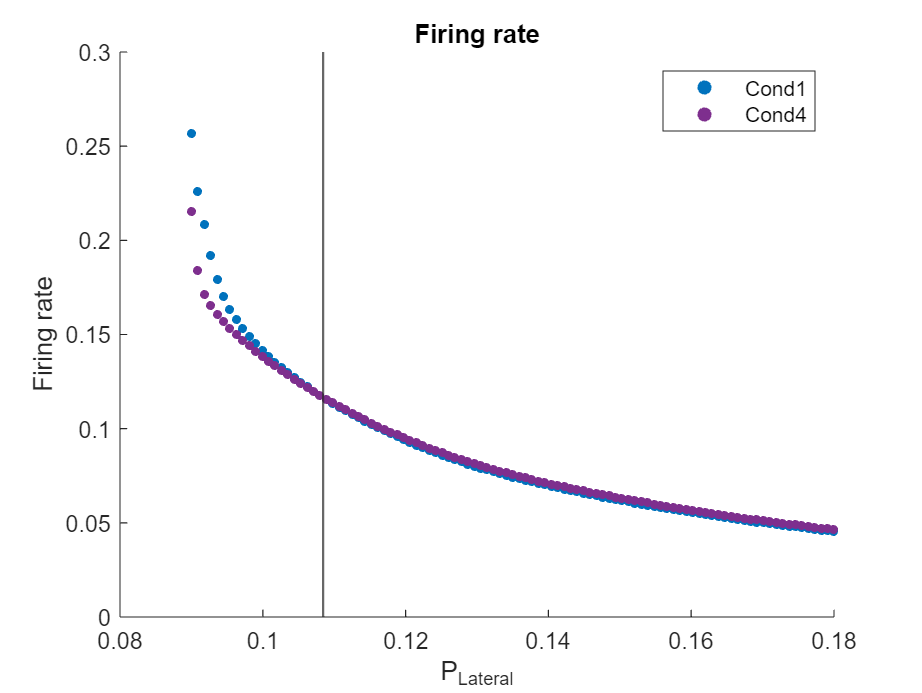

load lateral\finalR_cLateral_0.09_0.18_DeltaE_0.3_DeltaI_0.026_Iattn_0.02.mat
addpath('funcs');

lateral_start = 0.09;
lateral_end = 0.18; 

steps = 100;

sz = 15;
x = linspace(lateral_start,lateral_end,size(PETAsheet,1));
y1 = finalRsheet(:,5,1);
y4 = finalRsheet(:,5,4);

% % find zero point
z = y1 - y4; 
[~, idxP] = min(z(z>0));
x0 = (x(idxP) + x(idxP+1))/2;

figure();
s1 = scatter(x,y1,sz,'filled','MarkerFaceColor','#0072BD');
hold on;
s4 = scatter(x,y4,sz,'filled','MarkerFaceColor','#7E2F8E');
xline(x0,'LineWidth',1);

title("Firing rate");
legend([s1 s4],["Cond1","Cond4"],"Location","Northeast");
xlabel("P_{Lateral}");
ylabel("Firing rate");

## Lateral Pathway

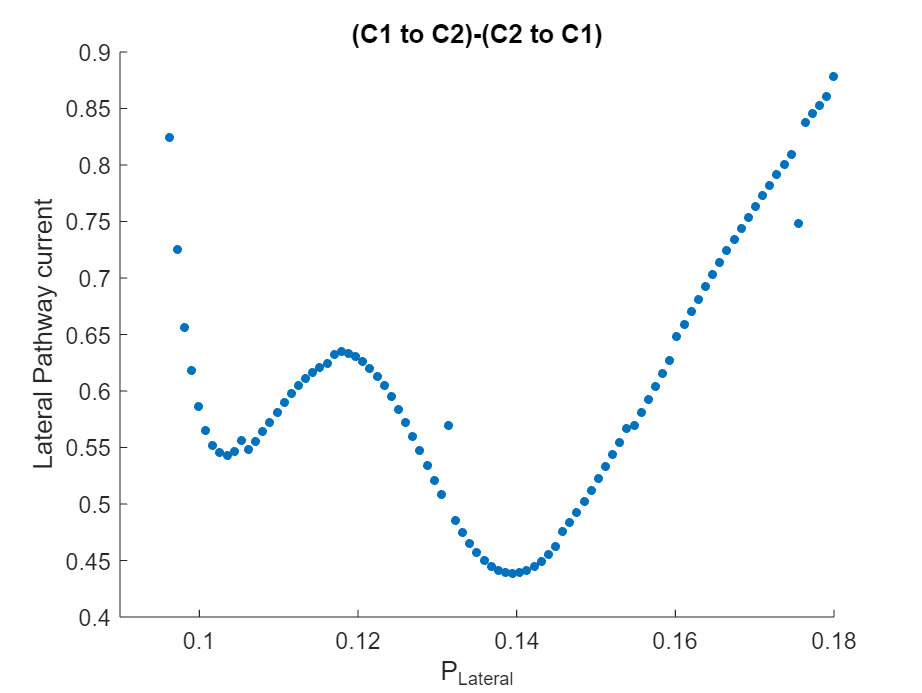

load lateral\finalR_cLateral_0.09_0.18_DeltaE_0.3_DeltaI_0.026_Iattn_0.02.mat
addpath('funcs');

lateral_start = 0.09;
lateral_end = 0.18; 

steps = 100;

sz = 15;
x = linspace(lateral_start,lateral_end,size(PETAsheet,1));
y1 = PETAsheet(:,10,1,4);
y2 = PETAsheet(:,2,9,4);

% % find zero point
% z = y2 - y1; 
% [~, idxP] = min(z(z>0));
% x0 = (x(idxP) + x(idxP+1))/2;

figure();
s1 = scatter(x,y1-y2,sz,'filled','MarkerFaceColor',"#0072BD");
% hold on;
% s2 = scatter(x,y2,sz,'filled','MarkerFaceColor',"#D95319");
% xline(x0,'LineWidth',1);

xlim([0.1 0.18]);
axis([0.09 0.18 0.4 0.9]);
title("(C1 to C2)-(C2 to C1)");
% legend([s1 s2],["C1 to C2","C2 to C1"],"Location","Southeast");
xlabel("P_{Lateral}");
ylabel("Lateral Pathway current");

## PET

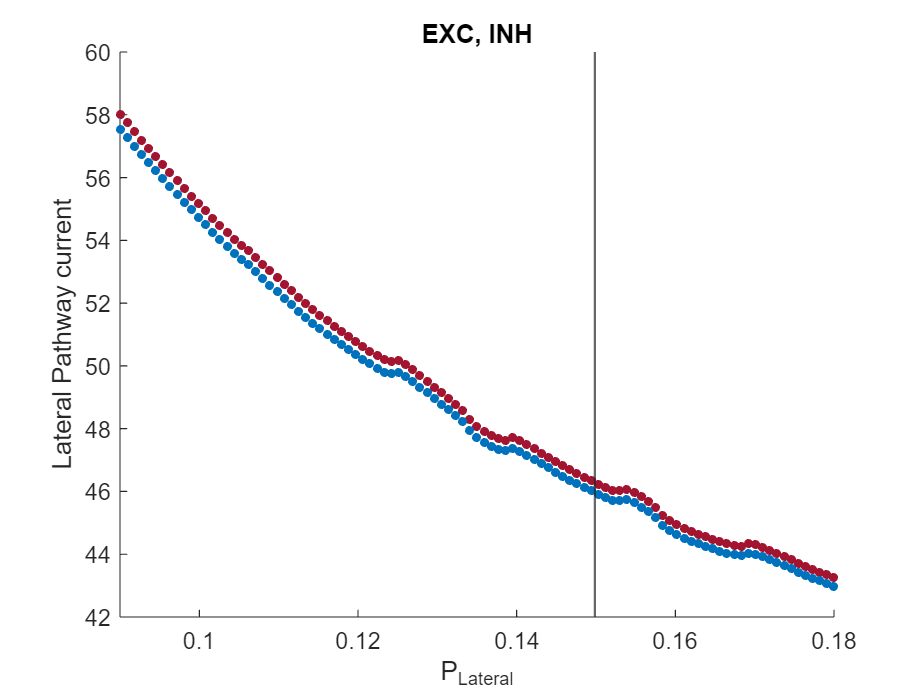

load lateral\finalR_cLateral_0.09_0.18_DeltaE_0.3_DeltaI_0.03_Iattn_0.02.mat
addpath('funcs');

lateral_start = 0.09;
lateral_end = 0.18; 

steps = 100;

sz = 15;
x = linspace(lateral_start,lateral_end,size(PETAsheet,1));
exc1 = PETAsheet(:,1,1,4)+PETAsheet(:,1,3,4)+PETAsheet(:,1,5,4)+PETAsheet(:,1,7,4);
inh1 = PETAsheet(:,1,2,4)+PETAsheet(:,1,4,4)+PETAsheet(:,1,6,4)+PETAsheet(:,1,8,4);

exc2 = PETAsheet(:,9,9,4)+PETAsheet(:,9,11,4)+PETAsheet(:,9,13,4)+PETAsheet(:,9,15,4);
inh2 = PETAsheet(:,9,10,4)+PETAsheet(:,9,12,4)+PETAsheet(:,9,14,4)+PETAsheet(:,9,16,4);

y1 = PETAsheet(:,10,1,4);
y2 = PETAsheet(:,2,9,4);
% find zero point
z = y2 - y1; 
[~, idxP] = min(z(z>0));
x0 = (x(idxP) + x(idxP+1))/2;

figure();
s1 = scatter(x,exc1+inh1,sz,'filled','MarkerFaceColor',"#A2142F");
hold on;
s2 = scatter(x,exc2+inh2,sz,'filled','MarkerFaceColor',"#0072BD");
% s3 = scatter(x,exc2,sz,'filled','MarkerFaceColor',"#D95319");
% s4 = scatter(x,inh2,sz,'filled','MarkerFaceColor',"#4DBEEE");

xline(x0,'LineWidth',1);
% yline(0,'LineWidth',1);

xlim([0.09 0.18]);
title("EXC, INH");
% legend([s1 s2],["C1 to C2","C2 to C1"],"Location","Southeast");
xlabel("P_{Lateral}");
ylabel("Lateral Pathway current");